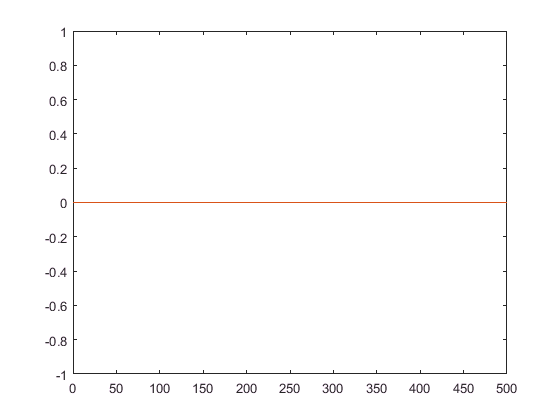

delete(instrfindall);
seriallist;
instrhwinfo;
s=serial('COM9');
fopen(s);
%fprintf(s,'*IDN?'); %eqv Serial.print

tic 
b=toc;
Varr=zeros(500,1);
Iarr=zeros(500,1);

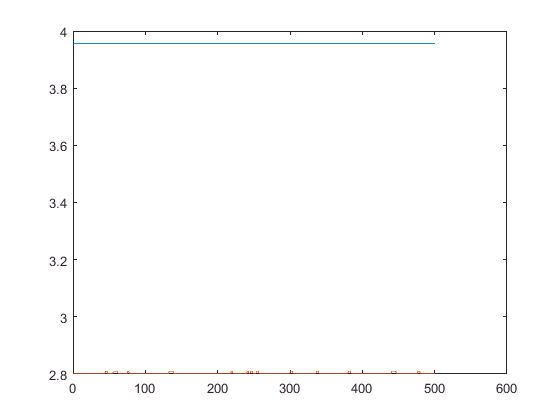

i=501;

while(toc-b<10)
if(i==501)
fscanf(s);
end
out = fscanf(s,'%f');%eqv Serial.read
Iarr(i)=out;

out = fscanf(s,'%f');%eqv Serial.read
Varr(i)=out;
hold off
plot(Varr(i-500:end))
hold on
plot(Iarr(i-500:end))
i=i+1;
end

%fprintf/fscanf/read
%fwrite
% https://in.mathworks.com/help/instrument/serial-port-interface.html

